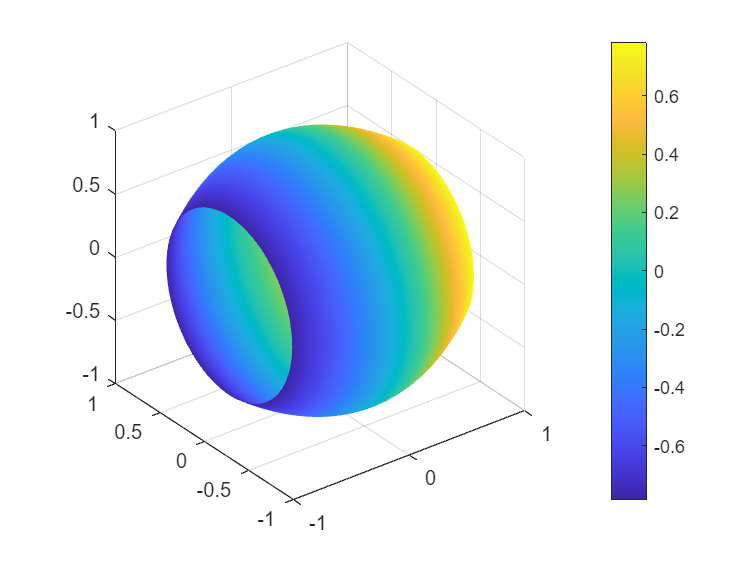

num_points = 100;
% x = linspace(0, 2, num_points);
% r = sqrt(x);
[X, Thetas] = meshgrid(-pi/4:(pi/2/1000):pi/4, 0:(2*pi/1000):2*pi);
Y = cos(X) .* cos(Thetas);
Z = cos(X) .* sin(Thetas);
C = X;
surf(X,Y,Z,C)
shading interp
axis square
colorbar

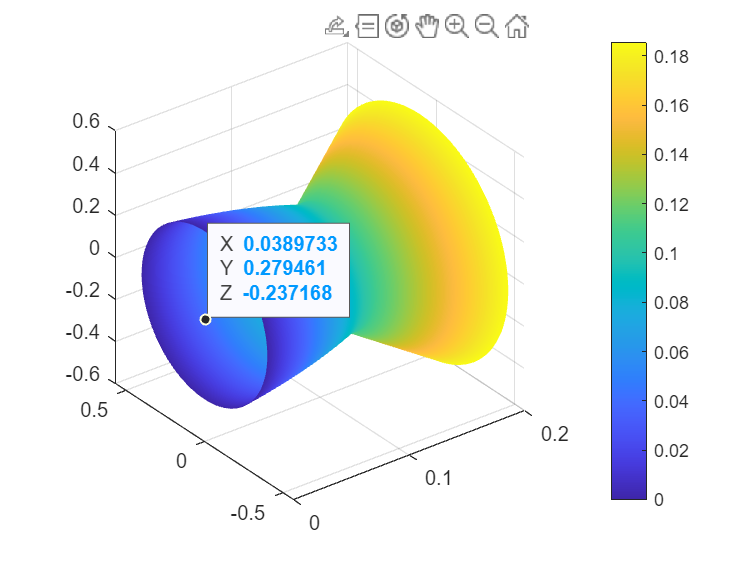

[X,Y,Z] = plot_nozzle(0.5, 0.25, 1, 0.1, 15);

save_to_stl(X, Y, Z, "sample_nozzle.stl");

    "Nozzle surface exported to "    "sample_nozzle.stl"



function [X,Y,Z] = plot_nozzle(A_inlet, A_throat, A_exit, inlet_len, angle)
    num_points = 100;
    r_inlet = sqrt(A_inlet/pi);
    r_throat = sqrt(A_throat/pi);
    r_exit = sqrt(A_exit/pi);
    outlet_len = (r_exit - r_throat) * tand(angle);
    throat_len = 0.1 * inlet_len;
    x_total = inlet_len + throat_len + outlet_len;
    x_step = x_total / num_points;
    [X, Thetas] = meshgrid(0:x_step:x_total, 0:(2*pi/1000):2*pi);
    R = (r_inlet + (r_throat - r_inlet) .* exp_scale(X ./ inlet_len)) .* (X <= inlet_len);
    R = R + r_throat .* (inlet_len < X & X <= (inlet_len + throat_len));
    R = R + (r_throat + ((r_exit - r_throat)/outlet_len .* (X - (inlet_len + throat_len)) )) .* ((inlet_len + throat_len) < X & X <= x_total);
    Y = R .* cos(Thetas);
    Z = R .* sin(Thetas);
    C = X;
    surf(X,Y,Z,C)
    shading interp
    axis square
    colorbar
end

function percentage=exp_scale(x)
    percentage = (exp(x) - 1) ./ (exp(1) - 1);
end

function save_to_stl(X, Y, Z, filename)
    [faces, vertices] = surf2patch(X, Y, Z, 'triangles');
    tr = triangulation(faces, vertices);
    stlwrite(tr, filename);    
    disp(['Surface exported to ', filename]);
end